clear
close all
%---setting
expri='ens02';   member=1:10;    lev=10:20;  
%year='2007'; mon='06'; date='01';
year='2018'; mon='06'; date='22';  hr=1:10;  minu=0;
dirmem='pert'; infilenam='wrfout';  dom='01';

indir=['E:/wrfout/expri_ens200323/',expri];
outdir='E:/figures/expri191009/';
titnam='KE spectral';   fignam=[expri,'_KE-sp_'];

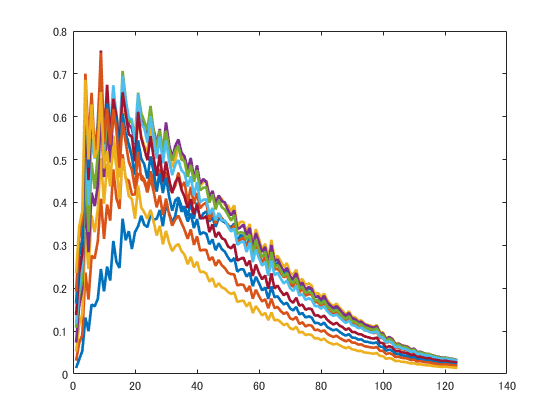

dx=1; dy=1;
nti=0;  n=0;  tmi=minu;
for ti=hr
    nti=nti+1;
for mi=member
   n=n+1; 
%---set filename---
s_hr=num2str(ti,'%.2d');  % start time string
s_min=num2str(tmi,'%.2d');
nen=num2str(mi,'%.2d');
infile=[indir,'/',dirmem,nen,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',s_min,'%3A00'];
%------read netcdf data--------
u.stag = ncread(infile,'U');u.stag=double(u.stag);
v.stag = ncread(infile,'V');v.stag=double(v.stag);
%---
u.unstag=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5;
v.unstag=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5;

if n==1
 [nx, ny, ~]=size(u.unstag); 
 Lx=dx*nx;  Ly=dy*ny;
 %dk=2*pi/max(Lx,Ly);
 %u.fft=zeors(nx,ny,length(lev)); 
 %v.fft=zeors(nx,ny,length(lev)); 
 KE_h=zeros(max(nx,ny)/2-1,length(member));
 
 for xi=1:nx/2-1
    for yi=1:ny/2-1
        nk(xi,yi)=(xi^2+yi^2)^0.5;
    end
 end
 nk2=round(nk);
 
 mKE_h=zeros(length(hr),max(nx,ny)/2-1);
end

KE=zeros(nx/2-1,ny/2-1);
for lvi=lev
 u.fft=fft2(u.unstag(:,:,lvi))/(nx*ny);
 v.fft=fft2(v.unstag(:,:,lvi))/(nx*ny);
 KE(:,:)=KE(:,:)+(abs(u.fft(2:nx/2,2:ny/2))+abs(v.fft(2:Lx/2,2:Ly/2)))/length(lev);
end


for ki=1:max(nx,ny)/2-1   % !!!! 算好一個nk矩陣，直接四捨五入!  
   KE_h(ki,mi)=sum(KE(nk2==ki));
end

mKE_h(nti,:)=mean(KE_h,2);

end
end

figure 
plot(mKE_h','LineWidth',2)